# refresh environment

clear all
clc
close all
restoredefaultpath;
addpath(genpath('.'));


## create a basic belief assignment (Slide 6-7)

N_classes = 4;
BetP = probability_class;
BetP.initialize(ones(N_classes,1)/N_classes);
disp("posterior:")

posterior:


disp(BetP.posterior);

    0.2500
    0.2500
    0.2500
    0.2500



m = BetP.ipig();
disp("BBA:")

BBA:


disp([m.mass]);

     1



disp([m.focal]);

   1
   1
   1
   1



disp([m.cardonality]);

     4



## create a contour function (Slide 8)


possibility = m.CF();
disp("Possibility Measure:")

Possibility Measure:


disp(possibility.measure);

     1
     1
     1
     1



## Fusion example (Slide 9)

BetP1 = probability_class;
BetP1.initialize([0.75 0.25]');
m1 = BetP1.ipig();
m2 = m1.copy();
disp("Fusion example chart 9:")

Fusion example chart 9:


disp("m1:")

m1:


disp([m1.mass]);

    0.5000    0.5000



disp([m1.focal]);

   1   1
   0   1



info_2_fuse(2) = info_class;
info_2_fuse(1).BBA = m1;
info_2_fuse(2).BBA = m2;
DST_obj = DST_class;
DST_obj.parameters.integrator.N_classes = 2;
DST_obj.parameters.integrator.flg.DP = false;
m12 = DST_obj.NROC(info_2_fuse,'DROC'); % fuse using conjunctive RoC
disp("m12:")

m12:


disp([m12.mass]);

    0.7500    0.2500



disp([m12.focal]);

   1   1
   0   1



## Root Proposition examples (Slide 11)

% row 1 example
class_names = {'A','B','C','D'};
N_classes = 3;
focal1 = false(N_classes,1);
focal1(1:2) = true;
disp("Root Proposition example 1:")

Root Proposition example 1:


disp("focal1:")

focal1:


disp([class_names{focal1}]);

AB


focal2 = false(N_classes,1);
focal2(2:3) = true;
disp("focal2:")

focal2:


disp([class_names{focal2}]);

BC


agg_source_focal = {focal1 focal2};
this_root_proposition = root_proposition(agg_source_focal,N_classes);
fprintf("Root Proposition: %s\n",class_names{this_root_proposition});

Root Proposition: B



% row 2 example
N_classes = 3;
focal1 = false(N_classes,1);
focal1(1) = true;
disp("Root Proposition example 2:")

Root Proposition example 2:


disp("focal1:")

focal1:


disp([class_names{focal1}]);

A


focal2 = false(N_classes,1);
focal2(2) = true;
disp("focal2:")

focal2:


disp([class_names{focal2}]);

B


focal3 = true(N_classes,1);
disp("focal3:")

focal3:


disp([class_names{focal3}]);

ABC


agg_source_focal = {focal1 focal2 focal3};
this_root_proposition = root_proposition(agg_source_focal,N_classes);
fprintf("Root Proposition: %s\n",class_names{this_root_proposition});

Root Proposition: A
Root Proposition: B



% row 3 example
N_classes = 4;
focal1 = false(N_classes,1);
focal1(1:2) = true;
disp("Root Proposition example 3:")

Root Proposition example 3:


disp("focal1:")

focal1:


disp([class_names{focal1}]);

AB


focal2 = false(N_classes,1);
focal2(3:4) = true;
disp("focal2:")

focal2:


disp([class_names{focal2}]);

CD


agg_source_focal = {focal1 focal2};
[~,bi_root_proposition] = root_proposition(agg_source_focal,N_classes);           
disp("Root Propositions:");

Root Propositions:


for i = 1 : size(bi_root_proposition,2)
    idx = find(bi_root_proposition(:,i));
    disp_str = sprintf('%s',class_names{idx(1)});
    for id = 2 : length(idx)
        disp_str = [disp_str ' U '];
        disp_str = [disp_str sprintf('%s',class_names{idx(id)})];
    end
    disp(disp_str);
end

A U B
C U D



% row 4 example
N_classes = 4;
focal1 = false(N_classes,1);
focal1(1:2) = true;
disp("Root Proposition example 4:")

Root Proposition example 4:


disp("focal1:")

focal1:


disp([class_names{focal1}]);

AB


focal2 = false(N_classes,1);
focal2(2:3) = true;
disp("focal2:")

focal2:


disp([class_names{focal2}]);

BC


focal3 = false(N_classes,1);
focal3(3:4) = true;
disp("focal3:")

focal3:


disp([class_names{focal3}]);

CD


agg_source_focal = {focal1 focal2 focal3};
[~,bi_root_proposition] = root_proposition(agg_source_focal,N_classes);           
disp("Root Propositions:");

Root Propositions:


for i = 1 : size(bi_root_proposition,2)
    idx = find(bi_root_proposition(:,i));
    disp_str = sprintf('%s',class_names{idx(1)});
    for id = 2 : length(idx)
        disp_str = [disp_str ' U '];
        disp_str = [disp_str sprintf('%s',class_names{idx(id)})];
    end
    disp(disp_str);
end

B
C



% row 5 example
N_classes = 3;
focal1 = false(N_classes,1);
focal1(1:2) = true;
disp("Root Proposition example 4:")

Root Proposition example 4:


disp("focal1:")

focal1:


disp([class_names{focal1}]);

AB


focal2 = false(N_classes,1);
focal2([1 3]) = true;
disp("focal2:")

focal2:


disp([class_names{focal2}]);

AC


focal3 = false(N_classes,1);
focal3(2:3) = true;
disp("focal3:")

focal3:


disp([class_names{focal3}]);

BC


agg_source_focal = {focal1 focal2 focal3};
[~,bi_root_proposition] = root_proposition(agg_source_focal,N_classes);           
disp("Root Propositions:");

Root Propositions:


for i = 1 : size(bi_root_proposition,2)
    idx = find(bi_root_proposition(:,i));
    disp_str = sprintf('%s',class_names{idx(1)});
    for id = 2 : length(idx)
        disp_str = [disp_str ' U '];
        disp_str = [disp_str sprintf('%s',class_names{idx(id)})];
    end
    disp(disp_str);
end

A
B
C


## Pignistic Transform Example (Slide 14)

m1 = BBA_class.empty;
m1(1).mass = 0.5;
m1(1).focal = [false true]';
m1(1).cardonality = 1;
m1(2).mass = 0.5;
m1(2).focal = true(2,1);
m1(2).cardonality = 2;
BetP1 = m1.pig();
disp(BetP1.posterior);

    0.2500
    0.7500



## Inverse Pignistic Transform Example (Slide 15)

BetP = probability_class;
BetP.initialize([0.1 0.4 0.2 0.3]');
m_consonant = BetP.ipig('consonant');
disp('consonant BBA:')

consonant BBA:


disp([m_consonant.mass]);

    0.1000    0.2000    0.3000    0.4000



disp([m_consonant.focal]);

   0   0   0   1
   1   1   1   1
   0   0   1   1
   0   1   1   1



m_bayesian = BetP.ipig('bayesian');
disp('bayesian BBA:')

bayesian BBA:


disp([m_bayesian.mass]);

    0.1000    0.4000    0.2000    0.3000



disp([m_bayesian.focal]);

   1   0   0   0
   0   1   0   0
   0   0   1   0
   0   0   0   1



## Consonant Belief Function Example (Slide 16)

possibility = possibility_class;
possibility.measure = [0.5 0.1 1 1]';
m = possibility.iCF();
disp('consonant BBA:')

consonant BBA:


disp([m.mass]);

    0.5000    0.4000    0.1000



disp([m.focal]);

   0   1   1
   0   0   1
   1   1   1
   1   1   1



## Removing Priors Example (Slide 19)

BetP = probability_class;
Prior = [0.0498 0.6375 0.2211 0.0916]';
BetP.initialize([0.0302 0.4683 0.4401 0.0614]',Prior);
BetP.remove_prior();
disp('Posterior:')

Posterior:


disp(BetP.posterior);

    0.0302
    0.4683
    0.4401
    0.0614



disp('Prior:')

Prior:


disp(BetP.prior);

    0.0498
    0.6375
    0.2211
    0.0916



disp('Likelihood:')

Likelihood:


disp(BetP.likelihood);

    0.1515
    0.1836
    0.4974
    0.1675



## see taxonomy of FODs (Slide 20)

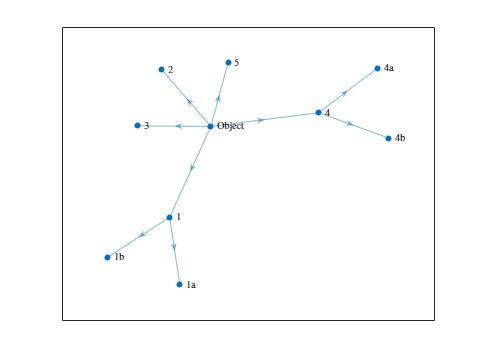

Taxonomy = digraph(1,2:6);
Taxonomy = addedge(Taxonomy,2,7:8);
Taxonomy = addedge(Taxonomy,5,9:10);
object_classes = {'Object','1','2','3','4','5','1a','1b','4a','4b'};
plot(Taxonomy,'Layout','force','NodeLabel',object_classes,'Interpreter','latex')

## Map Vocabulary 2 to Vocabulary 1 Example (Slide 21)


m1_theta2 = BBA_class.empty;
m1_theta2(1).mass = 0.25;
m1_theta2(1).focal = false(7,1);
m1_theta2(1).focal(1) = true;
m1_theta2(2).mass = 0.25;
m1_theta2(2).focal = false(7,1);
m1_theta2(2).focal([1 3]) = true;
m1_theta2(3).mass = 0.25;
m1_theta2(3).focal = false(7,1);
m1_theta2(3).focal([1 2 3]) = true;
m1_theta2(4).mass = 0.25;
m1_theta2(4).focal = false(7,1);
m1_theta2(4).focal([1 2 3 6]) = true;
FOD_mapping_obj = FOD_mapping_class;
FOD_mapping_obj.initialize('./parameters/Fusion_Tutorial_2023_FOD_set.prm');
m1_theta1 = FOD_mapping_obj.mapFOD(m1_theta2,'Vocabulary2','Vocabulary1');
disp("m1_theta2")

m1_theta2


disp([m1_theta2.mass]);

    0.2500    0.2500    0.2500    0.2500



disp([m1_theta2.focal]);

   1   1   1   1
   0   0   1   1
   0   1   1   1
   0   0   0   0
   0   0   0   0
   0   0   0   1
   0   0   0   0



disp("m1_theta1")

m1_theta1


disp([m1_theta1.mass]);

    0.2500    0.5000    0.2500



disp([m1_theta1.focal]);

   1   1   1
   0   1   1
   0   0   0
   0   0   1
   0   0   0



## Calibration Examples (Slide 23)

% Example 1
DST_obj = DST_class;
DST_obj.initialize('./parameters/Fusion_tutorial_2023_DST.prm','./parameters/Fusion_tutorial_2023_FOD_set.prm'...
    ,{'source1'},3,3);
DST_obj.source.track(1).given_info.probability.initialize([1 0 0]');
DST_obj.source.track(2).given_info.probability.initialize([0 1 0]');
DST_obj.source.track(3).given_info.probability.initialize([0 0 1]');
DST_obj.source.object_association_mat = ...
    [DST_obj.source.confusion_matrix.truthData(1).probability.posterior ...
    DST_obj.source.confusion_matrix.truthData(2).probability.posterior ...
    DST_obj.source.confusion_matrix.truthData(3).probability.posterior];
DST_obj.condition_source_data();
src_trks = [DST_obj.source.track.copy()];
cal_src_trks = [src_trks.calibrated_info];
cal_src_trks_prob = [cal_src_trks.probability];
disp("Calibrated Source Posterior:")

Calibrated Source Posterior:


disp([cal_src_trks_prob.posterior]);

    0.5000         0    0.5000
    0.2500    0.7500         0
    0.2500    0.2500    0.5000



cal_src_trks_poss = [cal_src_trks.possibility];
sys_trks = [DST_obj.source.object.copy()];
sys_trks_mapped = [sys_trks.mapped_info];
sys_trks_mapped_prob = [sys_trks_mapped.probability];
disp("Calibrated System Posterior:")

Calibrated System Posterior:


disp([sys_trks_mapped_prob.posterior]);

    0.5000    0.1250    0.3750
    0.1250    0.6250    0.2500
    0.3750    0.2500    0.3750



## Dempster's Rule Of Combination Example (Slide 30)

BetP1 = probability_class;
BetP1.initialize([0.75 0.25]');
m1 = BetP1.ipig();
BetP2 = probability_class;
BetP2.initialize([0.25 0.75]');
m2 = BetP2.ipig();
disp("DRoC example chart 30:")

DRoC example chart 30:


disp("m1:")

m1:


disp([m1.mass]);

    0.5000    0.5000



disp([m1.focal]);

   1   1
   0   1



disp("m2:")

m2:


disp([m2.mass]);

    0.5000    0.5000



disp([m2.focal]);

   0   1
   1   1



info_2_fuse(2) = info_class;
info_2_fuse(1).BBA = m1;
info_2_fuse(2).BBA = m2;
DST_obj = DST_class;
DST_obj.parameters.integrator.N_classes = 2;
DST_obj.parameters.integrator.flg.DP = false;
m12 = DST_obj.NROC(info_2_fuse,'DROC'); % fuse using conjunctive RoC
disp("m12:")

m12:


disp([m12.mass]);

    0.3333    0.3333    0.3333



disp([m12.focal]);

   0   1   1
   1   0   1



function [this_root_proposition, bi_root_proposition] = root_proposition(agg_source_focal,N_classes)
N_sources = length(agg_source_focal);
this_root_proposition = NaN(1,N_sources);
for is = 1 : N_sources
    this_root_proposition(is) = bi2de(reshape(agg_source_focal{is}...
        ,1,numel(agg_source_focal{is})));
end
this_root_proposition = unique(this_root_proposition);
N_roots = length(this_root_proposition);
flg_is_root_conflict = false(1,N_roots);
itter = 0;
while ~all(flg_is_root_conflict) && 1 < N_roots && itter <= 100
    itter = itter + 1;
    roots_matrix = triu(bitand(this_root_proposition',this_root_proposition),1);
    flg_is_root_conflict = ~any(roots_matrix,1) & ~any(roots_matrix,2)';
    new_root_conflict = unique(roots_matrix(roots_matrix>0))';
    this_root_proposition = [new_root_conflict this_root_proposition(flg_is_root_conflict)];
    N_roots = length(this_root_proposition);
end
bi_root_proposition = de2bi([this_root_proposition 2^(N_classes-1)]);
bi_root_proposition(end,:) = [];
bi_root_proposition = logical(bi_root_proposition');
end